%% Control difuso de calefacción (Mamdani) - Invernadero
% Entradas: Temperatura [0,40], Humedad [0,100]
% Salida: DeltaT [-15,15]
% Métodos: Mamdani clásico (min-max-centroid)

fis = mamfis("Name","Invernadero", ...
    "AndMethod","min", ...
    "OrMethod","max", ...
    "ImplicationMethod","min", ...
    "AggregationMethod","max", ...
    "DefuzzificationMethod","centroid");

%% 1) INPUT: Temperatura
fis = addInput(fis,[0 40],"Name","Temperatura");

% MFs (aprox. a la figura)
fis = addMF(fis,"Temperatura","trapmf",[0 0 10 15],"Name","MB");
fis = addMF(fis,"Temperatura","trimf",[10 15 20],"Name","B");
fis = addMF(fis,"Temperatura","trimf",[18 20 22],"Name","N");   % estrecha (como en la figura)
fis = addMF(fis,"Temperatura","trimf",[20 25 30],"Name","A");
fis = addMF(fis,"Temperatura","trapmf",[25 30 40 40],"Name","MA");

%% 2) INPUT: Humedad
fis = addInput(fis,[0 100],"Name","Humedad");

fis = addMF(fis,"Humedad","trapmf",[0 0 10 20],"Name","MB");
fis = addMF(fis,"Humedad","trimf",[10 25 40],"Name","B");
fis = addMF(fis,"Humedad","trimf",[30 40 50],"Name","N");
fis = addMF(fis,"Humedad","trimf",[40 55 70],"Name","A");
fis = addMF(fis,"Humedad","trapmf",[60 70 100 100],"Name","MA");

%% 3) OUTPUT: DeltaT
fis = addOutput(fis,[-15 15],"Name","DeltaT");

% 7 etiquetas: BG BN BP M SP SN SG (aprox. a la figura)
fis = addMF(fis,"DeltaT","trimf",[-15 -10 -7.5],"Name","BG");
fis = addMF(fis,"DeltaT","trimf",[-10 -5  -2.5],"Name","BN");
fis = addMF(fis,"DeltaT","trimf",[-7.5  -2.5   0],"Name","BP");
fis = addMF(fis,"DeltaT","trimf",[-1   0   1],"Name","M");
fis = addMF(fis,"DeltaT","trimf",[ 0   2.5   7.5],"Name","SP");
fis = addMF(fis,"DeltaT","trimf",[ 2.5   5  10],"Name","SN");
fis = addMF(fis,"DeltaT","trimf",[ 7.5  10  15],"Name","SG");

%% 4) Reglas (tabla 5x5)
% Índices de MFs:
% Temperatura: 1=MB 2=B 3=N 4=A 5=MA
% Humedad:     1=MB 2=B 3=N 4=A 5=MA
% DeltaT:      1=BG 2=BN 3=BP 4=M 5=SP 6=SN 7=SG

% Tabla dada:
% Temp MB: [SN SN SG SG SG] -> [6 6 7 7 7]
% Temp B : [M  M  SP SP SN] -> [4 4 5 5 6]
% Temp N : [M  M  M  M  BP] -> [4 4 4 4 3]
% Temp A : [M  M  BP BP BN] -> [4 4 3 3 2]
% Temp MA: [BP BN BN BG BG] -> [3 2 2 1 1]

ruleList = [
    1 1 6 1 1;  1 2 6 1 1;  1 3 7 1 1;  1 4 7 1 1;  1 5 7 1 1;
    2 1 4 1 1;  2 2 4 1 1;  2 3 5 1 1;  2 4 5 1 1;  2 5 6 1 1;
    3 1 4 1 1;  3 2 4 1 1;  3 3 4 1 1;  3 4 4 1 1;  3 5 3 1 1;
    4 1 4 1 1;  4 2 4 1 1;  4 3 3 1 1;  4 4 3 1 1;  4 5 2 1 1;
    5 1 3 1 1;  5 2 2 1 1;  5 3 2 1 1;  5 4 1 1 1;  5 5 1 1 1;
];

fis = addRule(fis,ruleList);

%% 5) Pruebas puntuales (valores concretos)
tests = [ ...
    20 50;   % T normal, H normal
    10 80;   % T baja, H alta
    30 20;   % T alta, H baja
    35 90];  % T muy alta, H muy alta

out = evalfis(fis,tests);
disp(table(tests(:,1),tests(:,2),out, ...
    'VariableNames',{'Temp','Hum','DeltaT'}));

    Temp    Hum    DeltaT 
    ____    ___    _______

     20     50           0
     10     80      10.835
     30     20     -5.9018
     35     90     -10.835



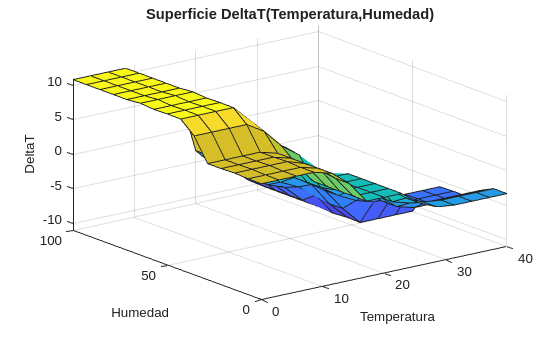


%% 6) Visualizar
% Reglas (interactivo):
% ruleview(fis)

% Superficie entrada/salida
figure;
gensurf(fis);  % Surface Viewer por código
title("Superficie DeltaT(Temperatura,Humedad)");



fis2 = fis;
fis2.AndMethod = "prod";
fis2.ImpMethod = "prod";


out1 = evalfis(fis, tests);
out2 = evalfis(fis2,tests);
disp(table(out1,out2,'VariableNames',{'minmin','prodprod'}));

    minmin      prodprod 
    _______    __________

          0    1.5306e-17
     10.835        10.835
    -5.9018       -5.8334
    -10.835       -10.835

